# Music with MATLAB

**Before you get started:**

This live script is intended to be used with the output on the right. On **View** tab of the MATLAB toolstrip, in the **View** section, select **Output on Right**. Alternately, select **Output on Right **using the icon 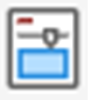 at the top right of the Live Editor pane.

  For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one, including running the code blocks in it.

  **Pro-tips**. The **Run Section ** command runs each line of code in a section. The   **Run** command runs each line of code in order from the beginning until the last line in the script. You can clear the output in the script in the **View** tab by clicking **Clear all Output**.

## 1. Fun MATLAB Functions

#### Clear the variables from the workspace by using the *clear* command.

clear

spy

knot
% Opens knot

why
%MATLAB answers all questions 
why
why
why
% How many different answers can you get from MATLAB? Try adding in more
% whys below.
why 
why

logo
% Displays MATLAB logo

sqrt(100)
% Squareroot of number


abs(-82.3925)
% Absolute value of number

## 2. Happy Birthday Song

#### Notes to the Birthday Song 

#### 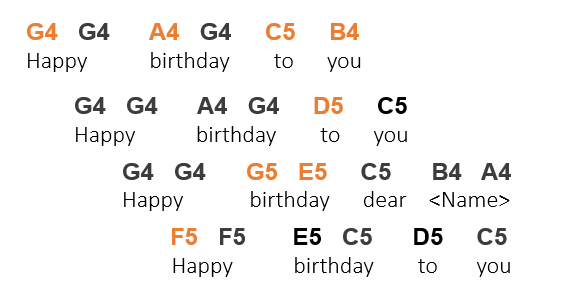

## Music Frequencies

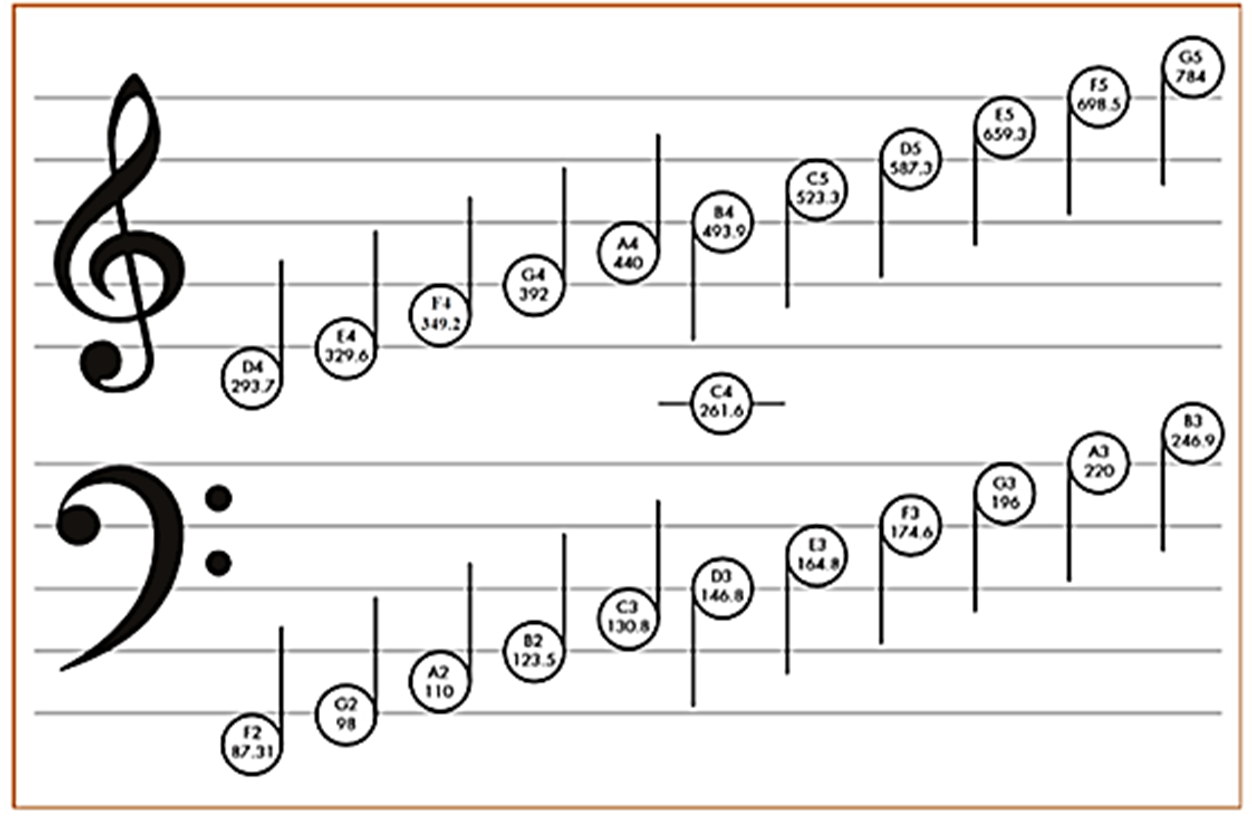

#### Create one variable for each unique note (highlighted orange) to store its frequency

G4 = 392;
A4 = 440;
C5 = 523.3;
B4 = 493.0;
E5 = 659.3;
D5 = 587.3;
G5 = 784 ;

#### Call sineSound() function to play the notes and pause to create rests in the music

% Use a combination of sineSound, and pause and the notes given in the
% Happy Birthday song, to create your own version of the Happy Birthday
% song.
sineSound(G4);
pause (0.2);
sineSound(G4);

sineSound(A4);

sineSound(G4);

#### Create vectors of tone frequencies and durations

% Fill in the remaining notes to create a frequency vector
freq = [G4 G4 A4 G4];
% Fill in the pause durations to create a t_dur vector
t_dur=[0.4  0.2  0.6  0.6]  

#### Use 'for' loop to play the tune

for i = 1 : 25
 sineSound(freq(i), t_dur(i));
pause(t_dur(i));
end

## 3. Create your own melody

% O   C       C#      D       Eb      E       F       F#      G       G#      A       Bb      B
% 0	16.35	17.32	18.35	19.45	20.60	21.83	23.12	24.50	25.96	27.50	29.14	30.87
% 1	32.70	34.65	36.71	38.89	41.20	43.65	46.25	49.00	51.91	55.00	58.27	61.74
% 2	65.41	69.30	73.42	77.78	82.41	87.31	92.50	98.00	103.8	110.0	116.5	123.5
% 3	130.8	138.6	146.8	155.6	164.8	174.6	185.0	196.0	207.7	220.0	233.1	246.9
% 4	261.6	277.2	293.7	311.1	329.6	349.2	370.0	392.0	415.3	440.0	466.2	493.9
% 5	523.3	554.4	587.3	622.3	659.3	698.5	740.0	784.0	830.6	880.0	932.3	987.8
% 6	1047	1109	1175	1245	1319	1397	1480	1568	1661	1760	1865	1976
% 7	2093	2217	2349	2489	2637	2794	2960	3136	3322	3520	3729	3951
% 8	4186	4435	4699	4978	5274	5588	5920	6272	6645	7040	7459	7902
% Source - http://www.seventhstring.com/resources/notefrequencies.html
 

### Create your variables using the musical frequencies above:

###  Use a combination of sineSound function, and pause function with the notes of your choosing to create your own melody.  

% DO NOT EDIT

function varargout = sineSound(varargin)
% Enveloping the sine wave of a Note or Chord
% env = sineSound(freq)
% env = sineSound(freq, time)

    Fs = 8000; 
    Ts = 1/Fs;
    
if nargin == 1
    freq = round(varargin{1},3);
    time = 0.2 ; 
    amp = 1;
    
elseif nargin == 2
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = 1;
    
elseif nargin == 3
    freq = round(varargin{1},3);
    time = round(varargin{2},3) ; 
    amp = varargin{3};
   
end

t = 0:Ts:time;
pure_sine = sin(2*pi*freq*t); 
step = 1/(length(t)/2); 
len = 1;
sine_coefficient = [(sin((pi* [0:step:len/2.0]) / (len))) ...
                        ones(1, length([len/2.0:step:len*3/2]) - 2)...
                        abs(sin((pi* [len*3/2:step:len*2.0]) / (len)))]; %#ok<*NBRAK>

env = 0.5*amp.*pure_sine.*sine_coefficient;


if nargout == 1
    varargout{1} = env';
else 
    sound(env, Fs);
end
end

© COPYRIGHT 2024 by MathWorks, Inc.